# Compile Figures for Upper Kuparuk River Basin, Alaska

%%%%%%
%Script for compiling the figure generator
%%%%%%

clear all
close all


%What is your project name?
ProjFolder = 'UpperKuparuk/';

%What is the original data?
originaldata = {'UK_synthesized_data.txt'};

%do you want the figure saved?
printfig  = true;

%Where do you want to save files?
workdirfigures = '~/Documents/GitHub/Permafrost_ERRA/datERRA/UK/figures/';

%Where is your data?
workdir = '~/Documents/GitHub/Permafrost_ERRA/datERRA/UK';




%Set directories
workdirfig_ = {workdirfigures, ProjFolder};
workdirfig=char(strcat(workdirfig_(1),workdirfig_(2)));
if ~exist(workdirfig, 'dir')
    cd(workdirfigures)
    mkdir(ProjFolder)
end
cd(workdir)

Lets plot the results

I know the units of Q, what should the units of P be? Rainfall is at units of mm, but is that per second? The ReadMe file says precipitation is recorded hourly and nothing more. The data file says units of [mm] recorded every hour, so is it per hour? Also it says its resolution is 0.1 mm per tip. What does per tip mean?

Catchment Size of Upper Kuparuk Basin at Gauge Site is 142km^2.

From Kane:

"2007 was a relatively dry year, although all three years were below the average rainfall (222 mm). The main storage mechanism for the Upper Kuparuk is the active layer. While positive storage followed immediately after snowmelt, relative storage went from positive to negative during the summer and remained negative for the remainder of the summer as ET + Q exceeded P. The timing of this transition was later for those years with greater rainfall. Note that a large tundra wildfire in 2007 northwest of the Upper Kuparuk burned from early summer into early winter, and was the largest documented fire on the North Slope of Alaska. 

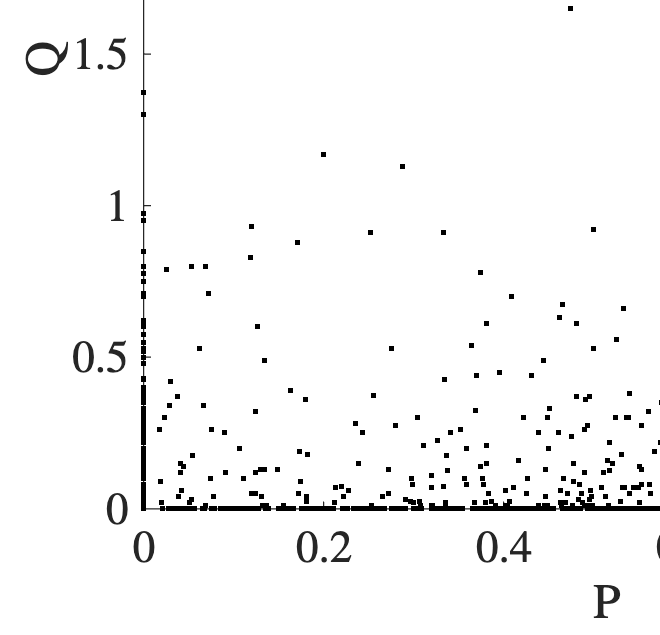

f2 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0.7000 12 6.6500 6.4000]
       Units: 'inches'

  Show all properties



% % %Plot time with discharge and precipitation. This function will change
% % %depending on data format. Please change this function accordingly
% % origdat=char(strcat(originaldata(1)));
% % f1 = figtQP_plot_UK(origdat,workdir,workdirfig,printfig)

%Plot P and Q as scatter. We use data from ERRA so this is standardized
f2 = figPQ_scatter(workdir,workdirfig,printfig,1)

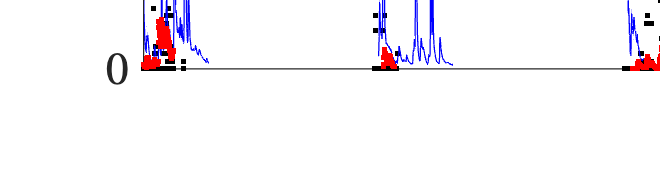

f3 =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [1 1 1]
    Position: [0.7000 12 21.6500 6.4000]
       Units: 'inches'

  Show all properties



%Plot ERRA time with real discharge, predicted discharge, and its residual
f3 = figtQQp_plot(workdir,workdirfig,printfig,1)

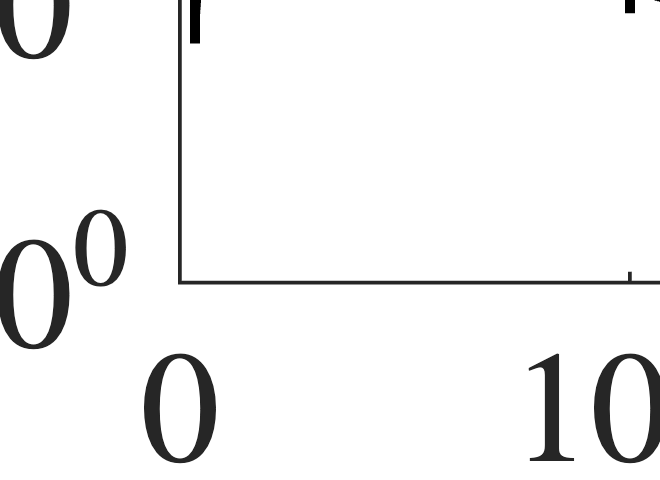

f4 =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [1 1 1]
    Position: [0.7000 12 9.3500 6.8000]
       Units: 'inches'

  Show all properties



%Plot lagtime with RRD
f4 = figtRRD_plot('Upper Kuparuk River',workdir,workdirfig,printfig,1)

% Load the data
opts = detectImportOptions('/Users/cansu/Documents/GitHub/Permafrost_ERRA/rawdata/UK_synthesized_data.txt');
data = readtable('/Users/cansu/Documents/GitHub/Permafrost_ERRA/rawdata/UK_synthesized_data.txt', opts);

% Convert columns to usable variables
P = data.P;        % Rainfall (mm/hr)
Q = data.Q;        % Runoff (streamflow normalized by area, mm/hr)

% Total rainfall and runoff
total_rainfall = nansum(P);  % Sum while ignoring NaNs
total_runoff = nansum(Q);

% Runoff ratio as percentage
runoff_ratio_percent = (total_runoff / total_rainfall) * 100;

% Display result
fprintf('Runoff Ratio: %.2f%%\n', runoff_ratio_percent);

Runoff Ratio: 118.33%


% Load your data (adjust filename or import manually if needed)
data = readtable('/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/UK/1hr_simple_RRD.txt');


% Extract variables
lagtime = data.lagtime;           % in hours
RRD_p_all = data.RRD_p_all;       % unitless (e.g., runoff ratio)
lagtime_hours = lagtime;

% Compute area under curve using trapezoidal integration
auc = trapz(lagtime_hours, RRD_p_all);

% Display result
fprintf('Area under RRD_p|all curve: %.6f (unitless)\n', auc);

Area under RRD_p|all curve: 0.570888 (unitless)
